# MRI

## **Setup**

Magnet - 

constant magnet field - as in our experiment

Gradient coils - 

help us to distinguish between (X, Y, Z) tissues

RF Coil(s)-

Pulses generators

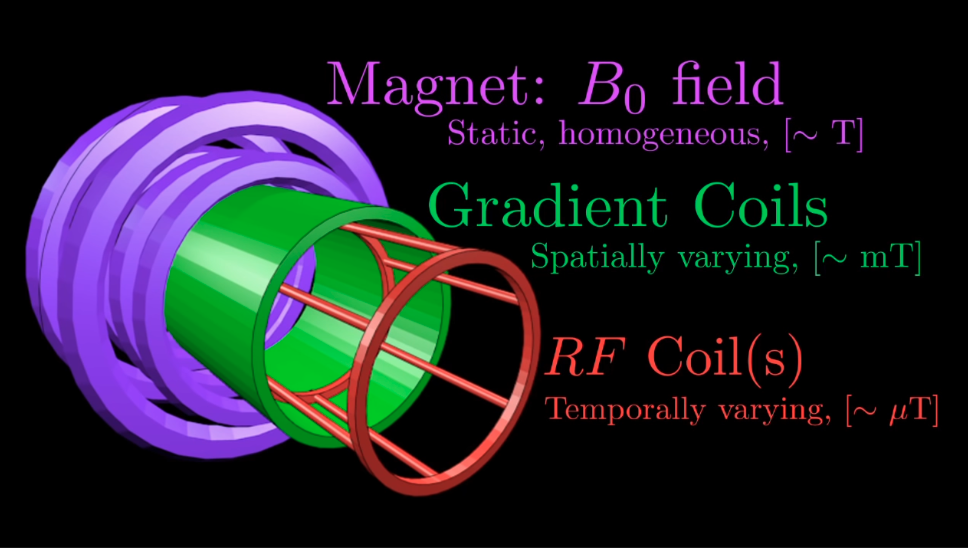

## 
$$H_z \left(y\right)=H_0 +\mathrm{gy}$$


## 
$$\omega \left(y\right)=\omega_0 +\gamma \mathrm{gy}$$


## 
$$\omega \left(z\right)\longleftrightarrow \mathrm{Rf}\;\mathrm{signal}$$


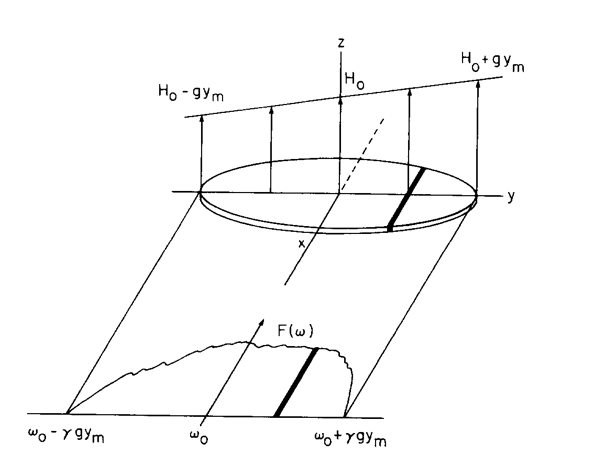

## T1 Relaxation time 

the time that we acquire the signal distinguish the tissues signal power, and corresponded to the TR time that we chose

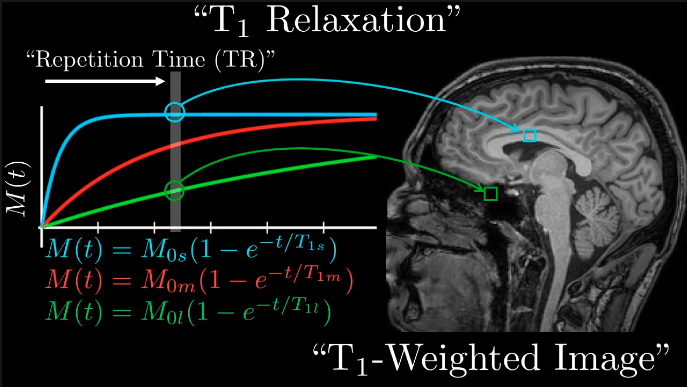

## T2 Relaxation time

constant make the signal distinct from sample to sample and the echo time will correspond to the contract in the imaging

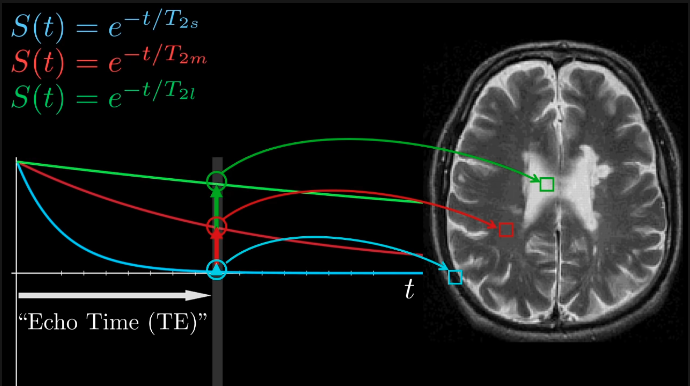

Along with the Magnetization equilibrium value that depends on the number of protons in the tissue we can chose the contract of the imaging by the organ.

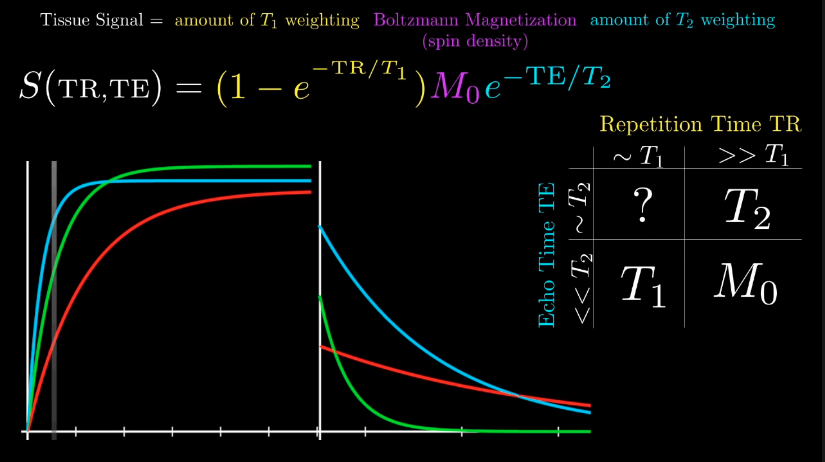

we can take the T1 results and lock for glycerin for example, assuming that the viscosity is a negative result in an MRI 

we will take the sample piece and normalized it to 0-1 range grey image. Let assume that glycerin is 0.3 T1 or T2 or M0 in the method we chosen.

we build a strip of tissues: 

T=readmatrix("ima_table.xlsx")

T =          0         0         0         0         0         0    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.3000    0.3000    0.3000    0.3000    0.3000    0.3000    0.4500    0.4500    0.4500    0.4500    0.4500    0.4500    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.7500    0.7500    0.7500    0.7500    0.7500    0.7500
         0         0         0         0         0         0    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.3000    0.3000    0.3000    0.3000    0.3000    0.3000    0.4500    0.4500    0.4500    0.4500    0.4500    0.4500    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.7500    0.7500    0.7500    0.7500    0.7500    0.7500
         0         0         0         0         0         0    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.3000    0.3000    0.3000    0.3000    0.3000    0.3000    0.4500    0.4500    0.4500    0.4500    0.4500    0.4500    0.6000    0.6000    0.6000    

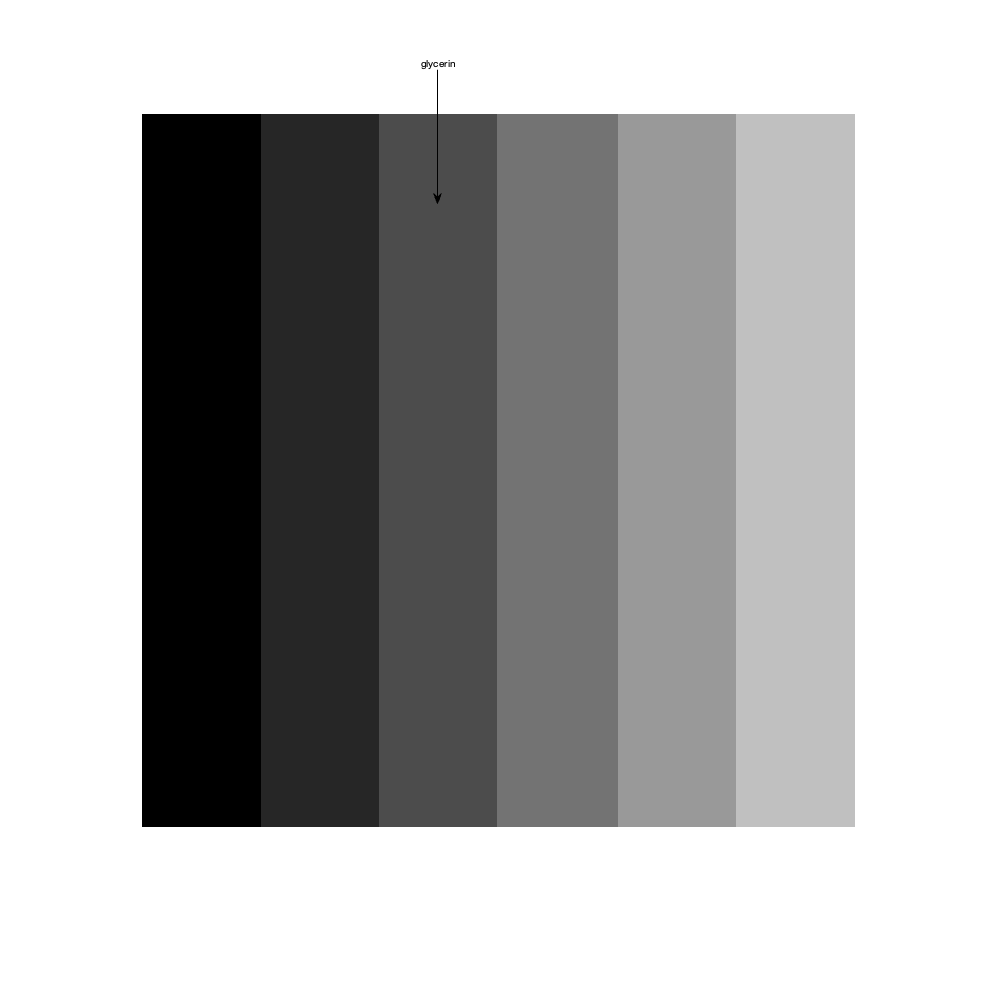


% T = filter2(fspecial('sobel'),T);
% T=mat2gray(T)
figure
imshow(imread('scale.png'))
set(gcf,'position',[0,0,1000,1000])

annotation("textarrow",[0.4375 0.4375],[0.9303 0.7963],"String","glycerin")

Now we can look for Gly in someone Brain MRI scan:

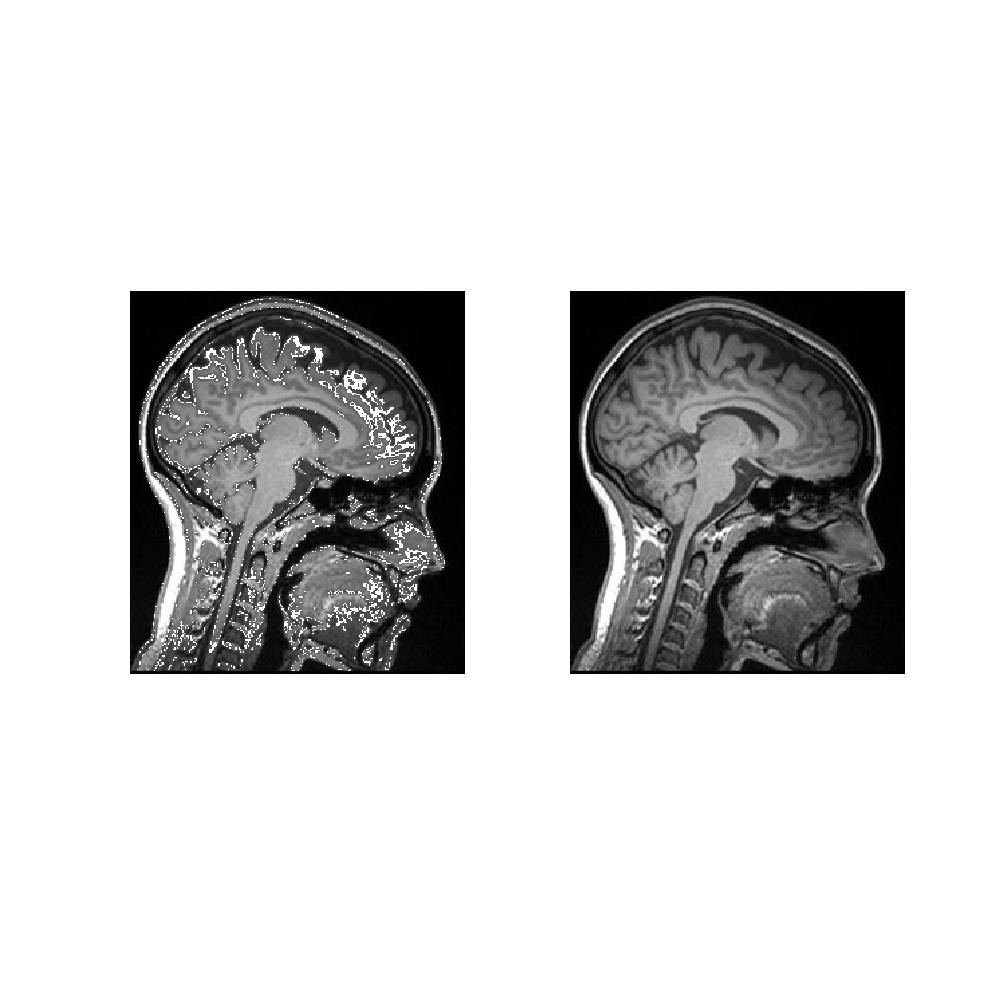

imdata = imread('MRI_BRAIN_SCAN.jpg');
imdata1 = mat2gray(imdata);
imdata2 = mat2gray(imdata);
imdata2(imdata2<0.37 & imdata2>0.33)=255;

figure
subplot(1,2,1)
imshow(imdata2)
subplot(1,2,2)
imshow(imdata1);
set(gcf,'position',[0,0,1000,1000])